clear all;
close all;

 
 %Ask for either of 12 Euler angle transitions
 disp("These are: XYZ,XZY,XYX,XZX,YXZ,YZX,YXY,YZY,ZXY,ZYX,ZXZ,ZYZ.");

These are: XYZ,XZY,XYX,XZX,YXZ,YZX,YXY,YZY,ZXY,ZYX,ZXZ,ZYZ.



 order = input('Enter either of 12 Euler angles possibilities: ','s'); 
 phi = input('Enter first angle: '); phi = phi*pi/180;
 theta = input('Enter second angle: '); theta = theta*pi/180;
 psi = input('Enter third angle: '); psi = psi*pi/180;
 PAB = zeros(3,1);
 disp("Enter corresponding PAB values: ") %Position Vector of Frame B in Frame A 

Enter corresponding PAB values: 


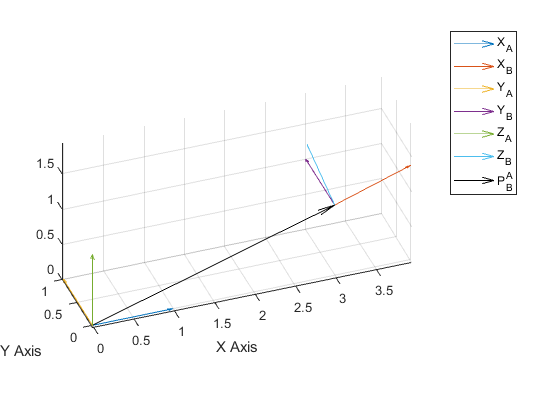

 PAB(1,1) = input("What is your translation along x-axis?");
 PAB(2,1) = input("What is your translation along y-axis?");
 PAB(3,1) = input("What is your translation along z-axis?");
 
     switch order
         case 'XYZ'
             R_1 = [1 0 0;0 cos(phi) -sin(phi);0 sin(phi) cos(phi)];
             R_2 = [cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)];
             R_3 = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0;0 0 1];
         case 'XZY'
             R_1 = [1 0 0;0 cos(phi) -sin(phi);0 sin(phi) cos(phi)];
             R_2 = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1];
             R_3 = [cos(psi) 0 sin(psi);0 1 0;-sin(psi) 0 cos(psi)];
         case 'XYX'
             R_1 = [1 0 0;0 cos(phi) -sin(phi);0 sin(phi) cos(phi)];
             R_2 = [cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)];
             R_3 = [1 0 0;0 cos(psi) -sin(psi);0 sin(psi) cos(psi)];
         case 'XZX'
             R_1 = [1 0 0;0 cos(phi) -sin(phi);0 sin(phi) cos(phi)];
             R_2 = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1];
             R_3 = [1 0 0;0 cos(psi) -sin(psi);0 sin(psi) cos(psi)];
         case 'YXZ'
             R_1 = [cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)];
             R_2 = [1 0 0;0 cos(theta) -sin(theta);0 sin(theta) cos(theta)];
             R_3 = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0;0 0 1];
         case 'YZX'
             R_1 = [cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)];
             R_2 = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1];
             R_3 = [1 0 0;0 cos(psi) -sin(psi);0 sin(psi) cos(psi)];
         case 'YXY'
             R_1 = [cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)];
             R_2 = [1 0 0;0 cos(theta) -sin(theta);0 sin(theta) cos(theta)];
             R_3 = [cos(psi) 0 sin(psi);0 1 0;-sin(psi) 0 cos(psi)];
         case 'YZY'
             R_1 = [cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)];
             R_2 = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1];
             R_3 = [cos(psi) 0 sin(psi);0 1 0;-sin(psi) 0 cos(psi)];
         case 'ZXY'
             R_1 = [cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1];
             R_2 = [1 0 0;0 cos(theta) -sin(theta);0 sin(theta) cos(theta)];
             R_3 = [cos(psi) 0 sin(psi);0 1 0;-sin(psi) 0 cos(psi)];
         case 'ZYX'
             R_1 = [cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1];
             R_2 = [cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)];
             R_3 = [1 0 0;0 cos(psi) -sin(psi); 0 sin(psi) cos(psi)];
         case 'ZXZ'
             R_1 = [cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1];
             R_2 = [1 0 0;0 cos(theta) -sin(theta);0 sin(theta) cos(theta)];
             R_3 = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0;0 0 1];
         case 'ZYZ'
             R_1 = [cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1];
             R_2 = [cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)];
             R_3 = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0;0 0 1];
         otherwise 
             disp('Unrecognized Transformation!')
     end
     
transformation_type = input("Enter 'C' or 'F' for transformations: ",'s');
      
        if transformation_type == 'C' %Choice for Current frame transformation (post-multiplication)
             Rot_mat = R_1*R_2*R_3;
             
                elseif transformation_type == 'F' %Choice for fixed frame transformation (pre-multiplication)        
             Rot_mat = R_3*R_2*R_1;
        end
        
HMT = vertcat(horzcat(Rot_mat,PAB),[0 0 0 1]);

starting_axis=eye(3);
end_axis=starting_axis*Rot_mat;

for i=1:3
    quiver3(0,0,0,starting_axis(i,1),starting_axis(i,2),starting_axis(i,3),0);
    
hold on
quiver3(PAB(1),PAB(2),PAB(3),end_axis(i,1),end_axis(i,2),end_axis(i,3),0);
end

view([-19.80 34.80])
hold on
quiver3(0,0,0,PAB(1),PAB(2),PAB(3),0,'k')
axis equal
% %quiver3(PAB(1),PAB(2),PAB(3),PAtilda(1),PAtilda(2),PAtilda(3))
% plot3([PAB(1) PAtilda(1)], [PAB(2) PAtilda(2)], [PAB(3) PAtilda(3)],'k--');
% plot3([0 PAtilda(1)], [0 PAtilda(2)], [0 PAtilda(3)],'m--');

xlabel('X Axis')
ylabel('Y Axis')

legend('X_A','X_B','Y_A','Y_B','Z_A','Z_B','P^A_B','show','Location','northeastoutside')